clear ; clc;

wn = 10;
zeta = 0.14;

x0 = 5;
v0 = 10;
X0 = [x0; v0];

dt = 0.001;
T = 5;
t = 0:dt:T;


% RK4 single step
function Xn = rk4step(fun, t, X, h)
    k1 = fun(t, X);
    k2 = fun(t+h/2, X+h/2 * k1);
    k3 = fun(t+h/2, X+h/2 * k2);
    k4 = fun(t+h, X+h * k3);
    Xn = X + h/6 * (k1 + 2*k2 + 2*k3 + k4);
end

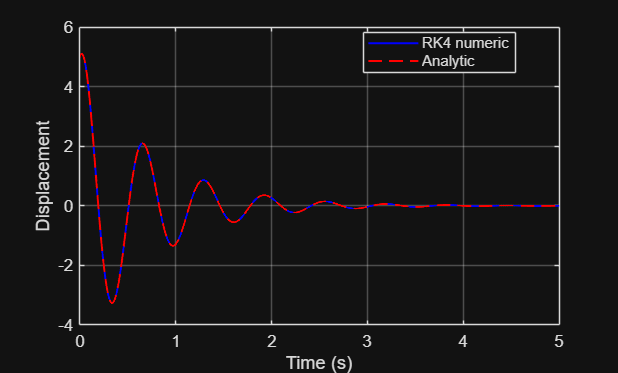


% ODE
f1 = @(t,X) [ X(2); -wn^2*X(1) - 2*zeta*wn*X(2)]; % Free Damped Vibration

% Integrate f1 with RK4
X1 = zeros(2, numel(t));
X1(:,1) = X0;
for i = 1:numel(t)-1
    X1(:,i+1) = rk4step(f1, t(i), X1(:,i), dt);
end
x_num = X1(1,:);

% Analytic solution
if zeta < 1
    % Underdamped
    wd = wn*sqrt(1 - zeta^2);
    A = x0;
    B = (zeta*wn*x0 + v0)/wd;
    x_analytic = exp(-zeta*wn*t) .* ( A.*cos(wd*t) + B.*sin(wd*t) );
elseif abs(zeta - 1) < 1e-12
    % Critically damped (zeta == 1)
    % x(t) = (A + B*t) * exp(-wn*t)
    A = x0;
    B = v0 + wn*x0;
    x_analytic = (A + B.*t) .* exp(-wn*t);
else
    % Overdamped (zeta > 1)
    r1 = -wn*(zeta - sqrt(zeta^2 - 1));
    r2 = -wn*(zeta + sqrt(zeta^2 - 1));
    C2 = (v0 - r1*x0) / (r2 - r1);
    C1 = x0 - C2;
    x_analytic = C1.*exp(r1.*t) + C2.*exp(r2.*t);
end

% Plot both
figure;
plot(t, x_num, 'b-', 'LineWidth', 1.2); hold on;
plot(t, x_analytic, 'r--', 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Displacement');
legend('RK4 numeric','Analytic','Location','best');
grid on; hold off;

w = 5;
F0 = 12;
deltast = F0 / wn^2;
r = w/wn;

% Forced Damped Vibration

f = @(t,X) [ X(2); -wn^2*X(1) - 2*zeta*wn*X(2) + wn^2*deltast*cos(w*t)];

% Integrate f with RK4
Y = zeros(2, numel(t));
Y(:,1) = X0;
for i = 1:numel(t)-1
    Y(:,i+1) = rk4step(f, t(i), Y(:,i), dt);
end
y_num = Y(1,:);

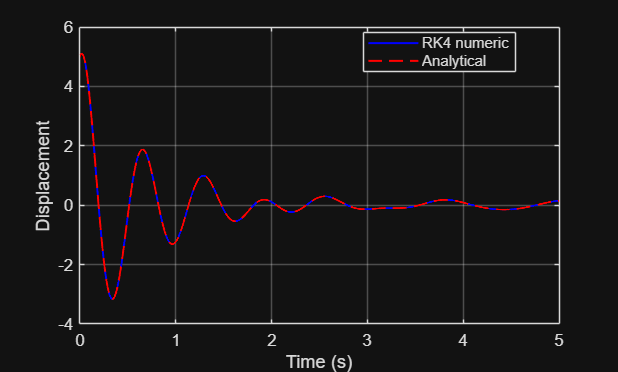

% Steady-state (particular) solution parameters
Xamp = deltast / sqrt((1 - r^2)^2 + (2*zeta*r)^2);
phi = atan2(2*zeta*r, 1 - r^2); 

xp = @(t) Xamp * cos(w*t - phi);
vp = @(t) -Xamp * w * sin(w*t - phi);

wd = wn * sqrt(1 - zeta^2);

A = x0 - xp(0);
B = (v0 - vp(0) + zeta*wn*A) / wd;

x_analytical = @(t) exp(-zeta*wn*t) .* (A*cos(wd*t) + B*sin(wd*t)) + xp(t);
x_ana = x_analytical(t);

% Plots
figure;
plot(t, y_num, 'b-', 'LineWidth', 1.2); hold on;
plot(t, x_ana, 'r--', 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Displacement');
legend('RK4 numeric', 'Analytical', 'Location', 'best');
grid on; hold off;

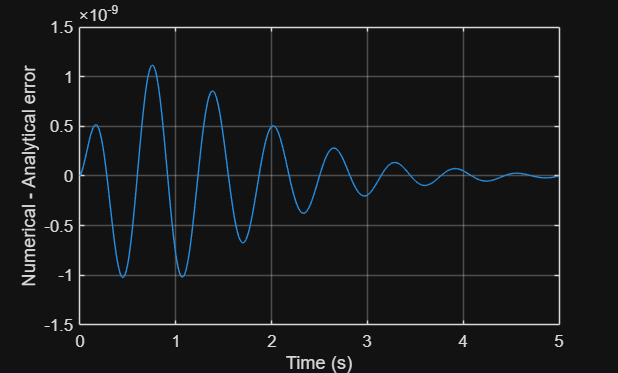

% Calculating error
error = y_num - x_ana;
figure;
plot(t, error);
xlabel('Time (s)'); ylabel('Numerical - Analytical error');
grid on;

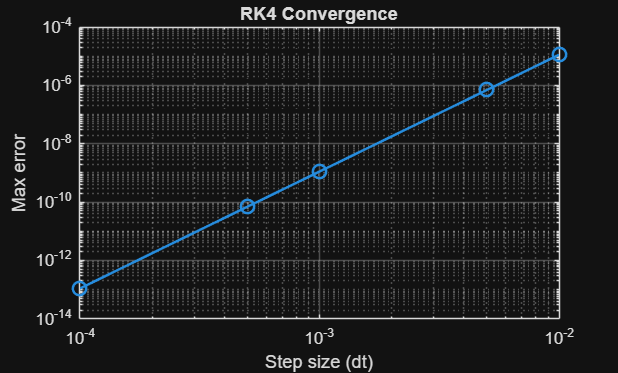

dts = [0.01, 0.005, 0.001, 0.0005, 0.0001];
max_errors = zeros(size(dts));

for k = 1:length(dts)
    dt_k = dts(k);
    t_k = 0:dt_k:T;
    
    X_k = zeros(2, numel(t_k));
    X_k(:,1) = X0;
    for i = 1:numel(t_k)-1
        X_k(:,i+1) = rk4step(f, t_k(i), X_k(:,i), dt_k);
    end
    x_num_k = X_k(1,:);
    x_ana_k = x_analytical(t_k);
    
    max_errors(k) = max(abs(x_num_k - x_ana_k));
end

figure;
loglog(dts, max_errors, 'o-', 'LineWidth', 1.5, 'MarkerSize', 8);
xlabel('Step size (dt)');
ylabel('Max error');
title('RK4 Convergence');
grid on;


p = polyfit(log(dts), log(max_errors), 1);
fprintf('Convergence order: %.2f\n', p(1));

Convergence order: 4.01
